# Ordinary Diferential Equation solution with Laplace Transform on Matlab

syms s t Y

.

f = '1 + (t-2-1)*Heaviside(t-3) + (2-(t-2))*Heaviside(t-6)'

f = '1 + (t-2-1)*Heaviside(t-3) + (2-(t-2))*Heaviside(t-6)'

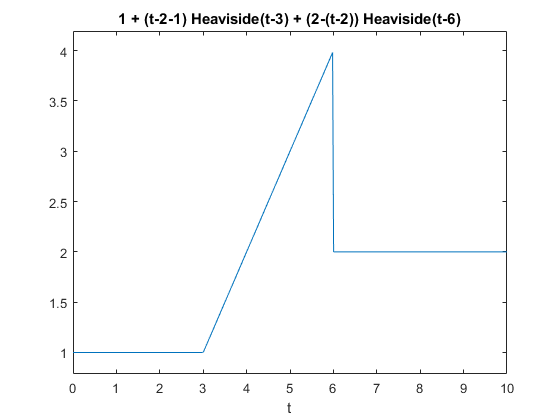

ezplot(f,[0,10])

F = laplace(f,t,s)

$$F = \frac{1}{s}+\mathrm{laplace}\left(t\,\mathrm{Heaviside}\left(t-3\right),t,s\right)-\mathrm{laplace}\left(t\,\mathrm{Heaviside}\left(t-6\right),t,s\right)-3\,\mathrm{laplace}\left(\mathrm{Heaviside}\left(t-3\right),t,s\right)+4\,\mathrm{laplace}\left(\mathrm{Heaviside}\left(t-6\right),t,s\right)$$


 
F =1/s + laplace(t*heaviside(t - 3), t, s) - laplace(t*heaviside(t - 6), t, s) - 3*laplace(heaviside(t - 3), t, s) + 4*laplace(heaviside(t - 6), t, s)

$$F = \frac{{\mathrm{e}}^{-3\,s}}{s^{2}}-\frac{2\,{\mathrm{e}}^{-6\,s}}{s}-\frac{{\mathrm{e}}^{-6\,s}}{s^{2}}+\frac{1}{s}$$

Y1 = s*Y - 2

$$Y1 = Y\,s-2$$

Y2 = s*Y1 - 3

$$Y2 = s\,\left(Y\,s-2\right)-3$$

Sol = solve(Y2+3*Y1+2*Y-F,Y)

$$Sol = \frac{2\,s+\frac{{\mathrm{e}}^{-3\,s}}{s^{2}}-\frac{2\,{\mathrm{e}}^{-6\,s}}{s}-\frac{{\mathrm{e}}^{-6\,s}}{s^{2}}+\frac{1}{s}+9}{s^{2}+3\,s+2}$$

sol = ilaplace(Sol,s,t)

$$sol = \begin{array}{l} 6\,{\mathrm{e}}^{-t}-\frac{9\,{\mathrm{e}}^{-2\,t}}{2}+\mathrm{heaviside}\left(t-3\right)\,\left(\frac{t}{2}+{\mathrm{e}}^{3-t}-\frac{{\mathrm{e}}^{6-2\,t}}{4}-\frac{9}{4}\right)-\mathrm{heaviside}\left(t-6\right)\,\left(\frac{t}{2}+{\mathrm{e}}^{6-t}-\frac{\sigma_{1}}{4}-\frac{15}{4}\right)-2\,\mathrm{heaviside}\left(t-6\right)\,\left(\frac{\sigma_{1}}{2}-{\mathrm{e}}^{6-t}+\frac{1}{2}\right)+\frac{1}{2}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{12-2\,t} \end{array}$$

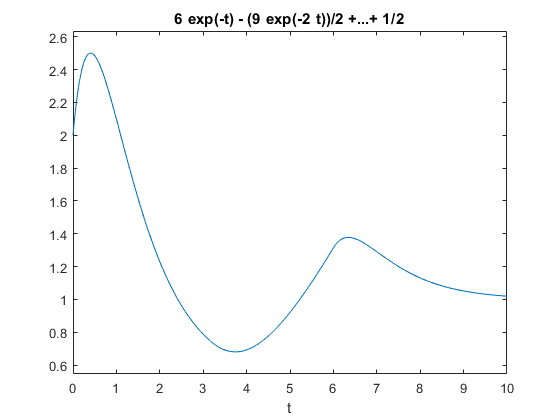

ezplot(sol,[0,10])